# ICE1 First-order Response and its Parameters

Define given TF:

a=3; b=-1; % polynomial coefficient
NUM = [b]; % numerator
DEN = [1, a]; % denominator
Dyn = tf(NUM,DEN); % TF as matlab object

Generate step response:

M = 6; % input amplitude
[y,t] = step(M*Dyn); % step response

Plot the response:

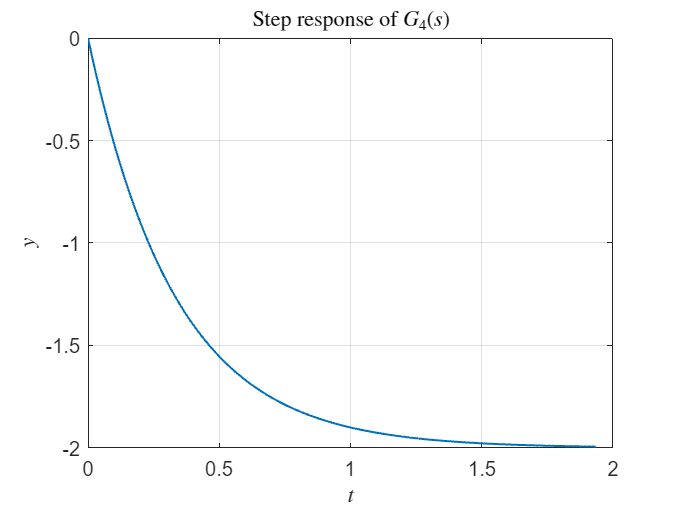

plot(t,y, 'LineWidth', 1)
grid
xlabel('$t$', 'Interpreter', 'latex')
ylabel('$y$', 'Interpreter', 'latex')
title('Step response of $G_4(s)$', 'Interpreter', 'latex')

Validate steady-state value:

SS = y(end)

SS = -1.9940

Verify time constant: 

tau = interp1(y, t, 0.63 * SS) % calculate time at 0.63 * SS

tau = 0.3298

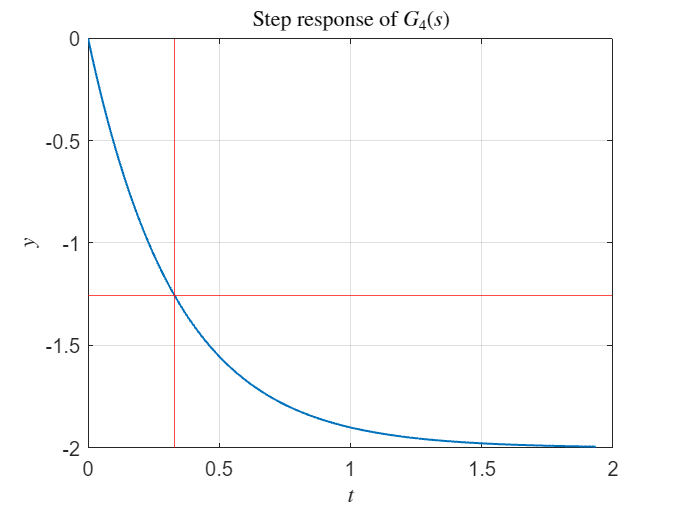

xline(tau, 'r')
yline(0.63 * SS, 'r')